# Symbolic variables definitions

clc;   clear;   close all ;
ref = CoolPropPyWrapper('HEOS::R134a');

CoolProp version: 6.4.1


% Load all symbolic variables
symbolicVariables

% Load hi-fi model data for operating point extraction
load('HiFi_model_data.mat')			

% CONSTANTS
INPUT_SCALE_MAX = 100;	% Inputs are scaled between 0 and this value
OMEGA_MAX = 140;		% Max value of compressor
THETA_MAX = 1;			% max value of valves
FAN_MAX = 1;			% max value of fan

% ========================================================================================
%                                 steady state variables
% ========================================================================================

% ========================= Temperatures =========================
% NOT USED
% ------------------------------
%T1															% [K] defined in constraints from T7
%T3															% [K] defined in constraints from T2 
%T4															% [K] Not defined from Condenser, never used
%T5															% [K] Not defined from Condenser Throttle valve, never used

% Operating points
T2			= 273.15 + out.logsout{28}.Values.Data(end,3);	% [K] - used in lookup
T6			= 273.15 + out.logsout{13}.Values.Data(end,3);	% [K] - ONLY used in lookup
T7			= 273.15 + out.logsout{26}.Values.Data(end,3);	% [K] - used in lookup


% ========================= Pressures =========================

% Operating points
p1        	= out.logsout{28}.Values.Data(end,1) * 1e5 ;	% [Pa] bar to pascal, 10^5 - used in lookup that is never used
p2			= out.logsout{25}.Values.Data(end,1) * 1e5 ;	% [Pa] defined in constraints
p3        	= out.logsout{3}.Values.Data(end,1)	 * 1e5 ;	% [Pa] 
p4          = out.logsout{13}.Values.Data(end,1) * 1e5 ;	% [Pa] 


% Table lookup, later linearised and used as constraint eq.
p5        	= out.logsout{26}.Values.Data(end,1) * 1e5 ;	% [Pa] - used in lookup

% ======================= Enthalpies =========================
% NOT USED
% ------------------------------
% h1														% a lookup, but never used (b.c. h2 is never used)
% h2														% defined in constraints, but never used
% h4														% defined in constraints, but never used
% h7         = ref.HTP(T7 - 273.15 , p5*1e-5);				% never used AT ALL

% Table lookups
%h3															% 
%h5         												% 
%h6         												% HTP uses p in bar.. DOES NOT ALIGN WITH: out.logsout{13}.Values.Data(end,2) 
%h_dew      												% average of pressure before and after evaporator


% ========================= Compressor =========================
V_1_COM1   	= 50e-6;										% 50 cm^3 - found in krestens guestimate?
V_1_COM2   	= V_1_COM1/2;									% 2nd stage is half the first
V_C_COM1   	= V_1_COM1*0.05;								% 5pct of pre stroke volume
V_C_COM2   	= V_1_COM2*0.05;								% 5pct of pre stroke volume
% gamma		= 1.2;											% freon r134a side 31 T=20 p=500kPa
kl_1       	= 1e5/2200;										% found in compressor script sent from kresten
kl_2       	= 1e5/2200;										% found in compressor script sent from kresten 

gammaT1 = (out.logsout{28}.Values.Data(end,3) + out.logsout{26}.Values.Data(end,3)) /2;
gammaP1 = (out.logsout{28}.Values.Data(end,1) + out.logsout{26}.Values.Data(end,1)) /2;
gammaT2 = (out.logsout{28}.Values.Data(end,3) + out.logsout{25}.Values.Data(end,3)) /2;
gammaP2 = (out.logsout{28}.Values.Data(end,1) + out.logsout{25}.Values.Data(end,1)) /2;

gamma1     = ref.CpRatioTP(gammaT1, gammaP1); %T=(22-5)/2 degC    p=(1.9+4.5)/2 bar,   see also freom r134a side 25
gamma2     = ref.CpRatioTP(gammaT2, gammaP2); %T=(48+22)/2 degC    p=(4.5+7.7)/2 bar,   see also freom r134a side 34



% Table lookups
% v_1_COM1													% p is from p_i1_COM1 - specific volume compressor in 
% v_1_COM2													% p is from p_i1_COM2 - Lookuptable defined below    


% ========================= Condenser =========================
UA_ma		= 650;											% found kresten PHD
UA_rm		= 1500;											% found kresten PHD
lambda		= 0.1;											% pressure drop constant, found in krestens sim model
Cp_m		= 387;											% evaporator and condeser metal (copper), kresten approve
M_m_Con		= 22.976;										% found in ??? (coefficient sheet?
V_i_Con		= 8*1e-3;										% GUESS of condenser volume


% Operating point
T_r			= 30 + 273.15;									% found in ???
v_Con		= 0.0008;										% pure guess. needs to be table look up later

% ========================= Evaporator =========================
UA_1      	= 3510;											% found in krestens phd
UA_2      	= 1930;											% found in krestens phd
UA_3      	= 50;											% found in krestens phd
V_i_Eva		= 11.9*0.001;									% is 11.9 L  - L->m3 ; from simulink->14*1.8*6*(0.005^2)*pi; %nr_pipes*length*area
Cp_air    	= 1003.5;										% heat capacity of air, google
rho_air		= 1.225;										% density of air
M_m_Eva		= 30;											% [kg] found coeff sheet - evaporator metal mass

% Table lookups
% T_lv
% v_Eva

% Operating points
% T_ret     	= out.logsout{15}.Values.Data(end,1);			% found in sim - return temperature % does not come out in celcius as opposed to other temperatures..


% ========================= Cargo =========================
M_air     	= (13.4*2.35*2.46)*rho_air;						% [kg] mass of air in box - H * L * B * air density
M_cargo   	= 1000;											% [kg] found in sim
Cp_cargo  	= 447;											% found in sim
UA_cargo  	= 20;											% found in sim


% ========================= Valve =========================
C_Val   	= 0.64;											% discharge coefficient
A_Val   	= ((20/2)^2)*pi*10^-6;							% Cross sectional area
% K_Val   	= C_Val*A_Val;									% collected constant
K_Val		= 1e-5;											% approximate value from krestens phd

% Condenser Throttle Valve
% ------------------------------
% Operating points
v_CTV_in	= 0.0008;										% found ???
rho_CTV		= 1/v_CTV_in;

% Expansion Valve
% ------------------------------
% Operating points
v_EV_in         = 0.01;										% found ???
rho_EV			= 1/v_EV_in;
% ========================= Box =========================
UA_ba      	= 25;    
UA_amb     	= 25;
Cp_box     	= 447;
M_box      	= 1000;
	

% ========================================================================================
%                  Operating points: inputs, states, disturbances                        
% ========================================================================================

% ========================= inputs =========================
% omega_op   = 28;			% [Hz]
% Theta_1_op = 19.5	/ 100;	% [%]
% Theta_2_op = 12.2	/ 100;	% [%]
% U_fan_1_op = 1500;			% [rpm] - 1600 is around half speed
% U_fan_2_op = 1500;			% [rpm] - 1600 is around half speed


% T_ambi_op = 273.15 + 20;	% [K]


% ========================= scaled inputs =========================
omega_op   = INPUT_SCALE_MAX * 0.2;			% [%] 100% = 140 Hz
Theta_1_op = INPUT_SCALE_MAX * 0.195;		% [%] 100% = 1
Theta_2_op = INPUT_SCALE_MAX * 0.122;		% [%]
U_fan_1_op = INPUT_SCALE_MAX * 0.4902;		% [%] 100% = 3060 rpm
U_fan_2_op = INPUT_SCALE_MAX * 0.4902;		% [%] 100% = 3060 rpm

% Disturbance input
T_ambi_op = 273.15 + 20;	% [K]



% ========================= states =========================
M_PJJ_OP       = 0.001; % 1 L * 1/specificVolume
% M_PJJ_OP       = 0.001 * (1/0.0481); % 1 L * 1/specificVolume
M_Con_OP       = 1;
T_m_OP         = 28.85 + 273.15;
m_dot_air_OP   = 0.25;     
T_mlv_OP       = -11.15 + 273.15; 
T_mv_OP        = -0.15 + 273.15;
M_lv_OP        = 0.5;
M_v_OP         = 0.0075;
T_air_OP       = 10 + 273.15; 
T_box_OP       = 10 + 273.15; 
T_cargo_OP     = 10 + 273.15;   



# Table lookups

% Placeholder table lookup functions
% syms tUpsilon tN tM tGamma tPI
% UpsilonLookup	= @(T, p)	tUpsilon*T*p;
% Nlookup			= @(p)		tN*p;
% Mlookup			= @(p)		tM*p;
% Gammalookup		= @(T, p)	tGamma*T*p;
% PIlookup		= @(h, p)	tPI*h*p;


% h3				= UpsilonLookup(T3, p2);				% COM2
% h3				= ref.HTP(T3,p2)
h3				= out.logsout{25}.Values.Data(end,2);
% h5				= Nlookup(p1);							% FT - dew/bub point
h5				= out.logsout{21}.Values.Data(end,2);	% supposed to be table lookup

% h6				= Mlookup(p1);							% FT - dew/bub point
h6         	= ref.HTP(T6 - 273.15, p4*1e-5);		% HTP uses p in bar.. DOES NOT ALIGN WITH: out.logsout{13}.Values.Data(end,2) 

% v_1_COM1		= Gammalookup(T7, p_i1_COM1);			% COM1
v_1_COM1		= 0.1234;								% ref.VTP(T3,1.9 - 4.5455e-04*omega_op) 
% v_1_COM2		= Gammalookup(T2, p_i1_COM2);			% COM2
v_1_COM2		= 7.61e-4;	
% p5				= PIlookup(h7, (V_i_Eva-V_lv)/M_v);	% Eva - 


% "non-official" - These are not mathematically defined as lookups in phd but are lookups anyway
% ------------------------------
v_Eva			= ref.VPX(p5*1e-5, 0.1);				% Eva - old value: 0.05; - v_l refrigerant specific volume Xe = 0.1
% v_Eva           = 0.0343;
T_lv			= ref.TBubP(1.9) + 273.15;				% Eva - ref.TBubP(1.9) / ref.TDewP(1.9) => same
h_dew      	    = ref.HDewP(p5*1e-5);	% Eva

% Never used
% ------------------------------
% h1			= Upsilonlookup(T1, p1)					% COM1  (never used b.c. h2 is never used)



% ========================================================================================
% linearisation of table look up
% ========================================================================================
%  p5
% ------------------------------
delta_X = 0.0001;  hv_op = 392030;  Vi_op = 0.0119;  Vl_op = 0.011;  M_v_linPoint = 0.0085; 

linearOffset_p5 = ref.PHD(hv_op, M_v_linPoint/(Vi_op-Vl_op));                        % Calculate f(p0) and f'(p0)
linearSlope_p5 = (ref.PHD(hv_op, (M_v_linPoint+delta_X)/(Vi_op-Vl_op)) - ...
	ref.PHD(hv_op, (M_v_linPoint-delta_X)/(Vi_op-Vl_op)) ) / (2*delta_X);


# Constraint equation and state definitions

% ========================================================================================
% Sorted constraints
% ========================================================================================

% Table lookups
p5              =       1e5 * (linearOffset_p5 + linearSlope_p5 * (M_v - M_v_linPoint));
% p5				=		out.logsout{26}.Values.Data(end,1) * 1e5 
% Load all contraints from constraints script
constraints_full_simulation

$$p1 = \frac{6668948122726147}{8589934592}-\frac{125000000000000000\,{\left(\frac{7\,\omega \,\left(\frac{5902958103587057\,{\left(-\frac{\frac{700\,\omega }{11}+\frac{1668967430757557}{2147483648}}{\frac{700\,\omega }{11}-\frac{965173581961105}{2147483648}}\right)}^{3787213908326499/4503599627370496}}{4722366482869645213696}-\frac{25}{761}\right)}{10}-M_{\mathrm{Con}}+10\right)}^{2}}{{\Theta_{2}}^{2}}$$

$$m\_dot\_5\_FT = \begin{array}{l} \frac{4294967296\,\left(\frac{10\,\left(1500\,T_{m}-454725\right)}{\sigma_{1}}-\frac{480064175852961}{17179869184}\right)\,\left(\frac{\sigma_{1}}{10}-M_{\mathrm{Con}}+10\right)}{2538124826959741}\\ \mathrm{where}\\ \sigma_{1}=7\,\omega \,\left(\frac{5902958103587057\,{\left(-\frac{\frac{700\,\omega }{11}+\frac{1668967430757557}{2147483648}}{\frac{700\,\omega }{11}-\frac{965173581961105}{2147483648}}\right)}^{3787213908326499/4503599627370496}}{4722366482869645213696}-\frac{25}{761}\right) \end{array}$$

$$p4 = \begin{array}{l} \frac{6668948122726147}{8589934592}-\frac{184467440737095516160000000000000000\,{\left(\frac{10\,\left(1500\,T_{m}-454725\right)}{\sigma_{2}}-\frac{480064175852961}{17179869184}\right)}^{2}\,\sigma_{1}}{6442077637229415194181234787081\,{\Theta_{1}}^{2}}-\frac{125000000000000000\,\sigma_{1}}{{\Theta_{2}}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\sigma_{2}}{10}-M_{\mathrm{Con}}+10\right)}^{2}\\ \sigma_{2}=7\,\omega \,\left(\frac{5902958103587057\,{\left(-\frac{\frac{700\,\omega }{11}+\frac{1668967430757557}{2147483648}}{\frac{700\,\omega }{11}-\frac{965173581961105}{2147483648}}\right)}^{3787213908326499/4503599627370496}}{4722366482869645213696}-\frac{25}{761}\right) \end{array}$$

$$m\_dot\_4\_FT = \begin{array}{l} M_{\mathrm{Con}}-\frac{\sigma_{1}}{10}-\frac{4294967296\,\left(\frac{10\,\left(1500\,T_{m}-454725\right)}{\sigma_{1}}-\frac{480064175852961}{17179869184}\right)\,\left(\frac{\sigma_{1}}{10}-M_{\mathrm{Con}}+10\right)}{2538124826959741}-10\\ \mathrm{where}\\ \sigma_{1}=7\,\omega \,\left(\frac{5902958103587057\,{\left(-\frac{\frac{700\,\omega }{11}+\frac{1668967430757557}{2147483648}}{\frac{700\,\omega }{11}-\frac{965173581961105}{2147483648}}\right)}^{3787213908326499/4503599627370496}}{4722366482869645213696}-\frac{25}{761}\right) \end{array}$$



% ========================================================================================
% State equations 
% ========================================================================================
errorRejection = (0.0099 -2.0300e-04 * omega*(OMEGA_MAX/INPUT_SCALE_MAX)); 
% Subtracted to omnit a derivative error

M_PJJ_dot		= m_dot_1 + m_dot_4_FT - m_dot_2_COM2;
M_Con_dot		= m_dot_2_COM2 - m_dot_3_Con;
T_m_dot			= (Q_rm - Q_ma)/(M_m_Con * Cp_m);
m_dot_air_dot	= (m_bar_dot_air - m_dot_air)/10;
T_mlv_dot		= (Q_amlv - Q_mlv + Q_mvmlv)/(M_m_Eva * sigma * Cp_m);
T_mv_dot		= (Q_amv - Q_mv - Q_mvmlv)/(M_m_Eva * (1- sigma) * Cp_m);
M_lv_dot	    = m_dot_5_FT -  m_dot_dew;
M_v_dot			= m_dot_dew - m_dot_1 - errorRejection;
T_air_dot       = (Q_ca + Q_ba + Q_fan_2 - Q_cool ) / (M_air + Cp_air);
T_box_dot       = (Q_amb - Q_ba ) / (M_box * Cp_box);
T_cargo_dot     = -Q_ca / (M_cargo * Cp_cargo);

f=[M_PJJ_dot;
   M_Con_dot;
   T_m_dot;
   m_dot_air_dot;
   T_mlv_dot;
   T_mv_dot;
   M_lv_dot;
   M_v_dot;
   T_air_dot;
   T_box_dot;
   T_cargo_dot];

## Simulation

Time = 5000 ;
Ts = 0.1;
no_samples = Time/Ts;
Time_vector = 0:Ts:Time-Ts;


% convert f to function handle with specific input variable order (inputs states)
f_func = matlabFunction(f, 'vars', [U_fan_1, U_fan_2, Theta_1, Theta_2, omega, T_ambi, ...
	M_PJJ, M_Con, T_m, m_dot_air, T_mlv, T_mv, M_lv, M_v, T_air,  T_box,  T_cargo]);
m_dot_4,m_dot_3_Val,m_dot_5_Val

$$m\_dot\_4 = {\dot{m}}_{4}$$

$$m\_dot\_3\_Val = {\dot{m}}_{3,\mathrm{Val}}$$

$$m\_dot\_5\_Val = {\dot{m}}_{5,\mathrm{Val}}$$


% initial conditions
% -------------------------------

% States
state_variables =	[M_PJJ; M_Con; T_m; m_dot_air; T_mlv; T_mv; M_lv; M_v; T_air; T_box; T_cargo];
state_init =		[M_PJJ_OP; M_Con_OP; T_m_OP; m_dot_air_OP; T_mlv_OP; T_mv_OP; M_lv_OP; M_v_OP; T_air_OP; T_box_OP; T_cargo_OP];

% Inputs + disturbance
input_variables = [U_fan_1, U_fan_2, Theta_1, Theta_2, omega, T_ambi];
input_OP_values = [U_fan_1_op, U_fan_2_op, Theta_1_op, Theta_2_op, omega_op, T_ambi_op];


clear states state_derivatives
states(:,1) = state_init;		% initialize states at first sample


% Convert [input, states] to cell array for input to f function
f_func_input = num2cell([input_OP_values, states(:,1)']);

% Generate new state derivatives
state_derivatives(:,1) = f_func(f_func_input{:});


% Simulation
% -------------------------------

for i=2:no_samples

    states(:,i) = states(:,i-1) + double(state_derivatives(:,i-1)) * Ts;
	
	f_func_input = num2cell([input_OP_values, states(:,i)']);			% Convert [input states] to cell array for input to f function
	state_derivatives(:,i) = f_func(f_func_input{:});					% Generate new state derivatives

end

% -------------------------------

## Plotting of simulation results


% indexes for plotting
plt_idx = [1:11];
plt_idx = [1:11];

mass_idx = [1 2 7 8];
temp_idx = [3 5 6 9 10];
flow_idx = [4];
legs = ["1: M_{PJJ}", "2: M_{Con}", "3: T_m", "4: m_{dot}_{air}", "5: T_{mlv}",...
	"6: T_{mv}", "7: M_{lv}", "8: M_{v}", "9: T_{air}",  "10: T_{box}",  "11: T_{cargo}"];


% limits
yl1 = [-5 500];
yl2 = [-10 10];
close all

ax1 = [];
myfig(1);
set(gcf,'Visible','on')
ax1(1) = subplot(2,1,1);
plot(Time_vector,states(plt_idx ,:)')

legend(legs(plt_idx ), 'Location', 'southeast')
grid on
title('States')
ylim(yl1)

ax1(2) = subplot(2,1,2);
plot(Time_vector,state_derivatives(plt_idx ,:)')

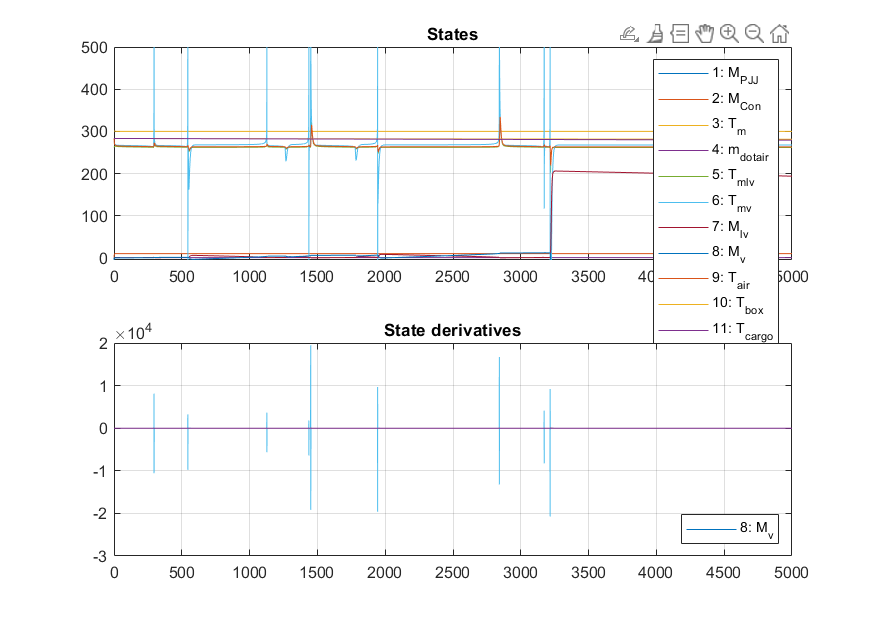

legend(legs(8 ), 'Location', 'southeast')
grid on
title('State derivatives')
% ylim(yl2)
linkaxes(ax1,'x')

# Linearisation

## A matrix

EQ_step = 5000;		% sample number for equilibrium 
% A_matrix = jacobian(f(1:end),[M_PJJ, M_Con, T_m, m_dot_air, T_mlv, T_mv, M_lv, M_v, T_air, T_box, T_cargo]);

A_syms = jacobian(f(3:end),[T_m, m_dot_air, T_mlv, T_mv, M_lv, M_v, T_air, T_box, T_cargo]);

OPparameters = [state_variables(3:end).' input_variables];
OPvalues    =[states(3:end, EQ_step)' input_OP_values];

A = double(subs(A_syms, OPparameters, OPvalues))

Error using symengine
Unable to convert expression containing symbolic variables into double array. Apply 'subs' function first to substitute values for variables.

Error in sym/double (line 800)
        Xstr = mupadmex('symobj::double', S.s, 0);

eig(A)

## B matrix

B_sym = jacobian(f(3:end),[omega, Theta_1, Theta_2, U_fan_1, U_fan_2]);

B = double(subs(B_sym, OPparameters, OPvalues))

## Bd matrix

Bd_sym = jacobian(f(3:end),[T_ambi]);
Bd = double(subs(Bd_sym, OPparameters, OPvalues))

## C matrix

% number of rows = number of outputs
C = [0 0 0 0 0 0 1 0 0];

# Assessment

## Condition number

condA = cond(A)
condCtrb = cond(ctrb(A,B))

p5_end = double(subs(p5, M_v, states(8,end)))

## Controllability

% what about M_PJJ and M_Con?
rank(ctrb(A,B))


## Observability

rank(obsv(A,C)) 

[Abar,Bbar,Cbar,T,k] = obsvf(A,B,C)

[sysrl, U] = minreal(ss(A,B,C,[0]))
A_tilde = U*A*U'
B_tilde = U*B
C_tilde = C*U'

# Controller / observer design

## LQR controller

Q = [ 1  0  0  0  0  0  0  0  0;
      0  1  0  0  0  0  0  0  0;
      0  0  1  0  0  0  0  0  0;
      0  0  0  1  0  0  0  0  0;
      0  0  0  0  1  0  0  0  0;
      0  0  0  0  0  1  0  0  0;
      0  0  0  0  0  0  1  0  0;
      0  0  0  0  0  0  0  1  0;
      0  0  0  0  0  0  0  0  1];

R = [1  0  0  0  0 
	0  1  0  0  0 
	0  0  1  0  0 
	0  0  0  1  0 
	0  0  0  0  1];

K = lqr(A, [B], Q, R)
t = 0:0.1:1000;


% [y,x] = lsim((A + [B Bd] *K),[B Bd],C,us,Input_OP_parameters,t); %do the simulation

% legs = ["1: M_{PJJ}", "2: M_{Con}", "3: T_m", "4: m_{dot}_{air}", "5: T_{mlv}",...
% 	"6: T_{mv}", "7: M_{lv}", "8: M_{v}", "9: T_{air}",  "10: T_{box}",  "11: T_{cargo}"];
% plot(t,y(:,3:11))
% legend(legs(3:11))



% FUNCTIONS


function normalizedInputs = inputNorm(inputs, max)
	% Scales the intputs to be inside a specific interval
	% input is array of inputs
	% max is max value (max = 100, range = 0->100)
	


end